# **Frequecy Features: Window, STFT**

Frequency Preprocessing and Features of 

- Windowing

- STFT

> Need to use  getFFT.m   See FFT_Exercise.mlx

# Windowing

We will learn how to apply hanning windowD

## Dataset

### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

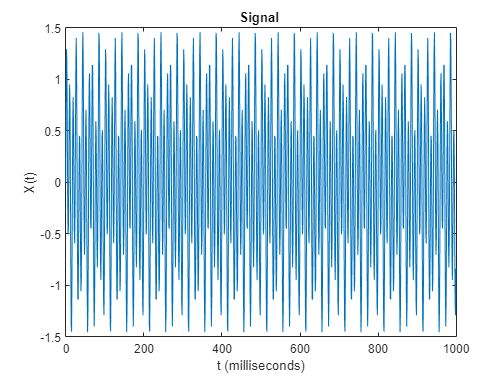

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 1000;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=50;      % 10Hz signal
fa2=120;    % 55Hz signal
X = 0.0 + 0.5* sin(2.0*pi*fa*t)+ 1*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

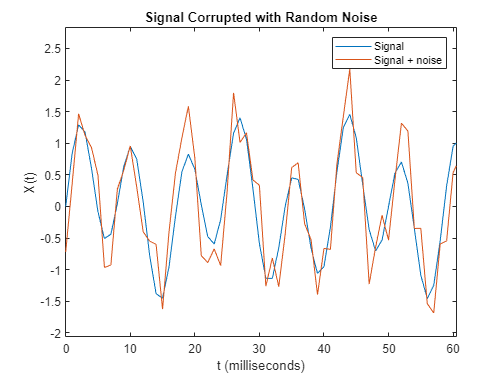

% Noise
noise= 0.5*randn(size(t));

% Mixed Signal
Xm = X+noise; 

% Plot signals
figure(1)
plot(1000*t,X, 1000*t,Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
legend('Signal','Signal + noise')
xlim([0 50])

## Apply Hanning Window

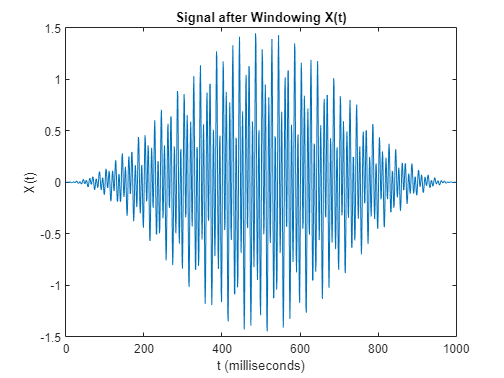

addpath('C:\Users\hanmu\Desktop\DigitalTwin\Functions');
L=N;
win=hanning(L);

% Apply window to X by multiplication
Xw = X' .* win;          

% Comraison for effect of window
[f, Po] = getFFT(Xw, L, Fs);
[f, Pa] = getFFT(Xw, L, Fs);

figure
plot(Xw)
title('Signal after Windowing X(t)')
xlabel('t (milliseconds)')
ylabel('X(t)')

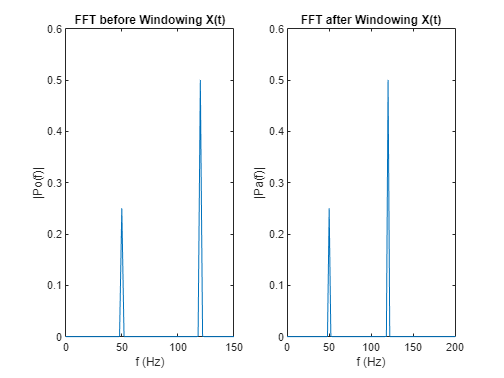

% Comparison
subplot(1,2,1);
plot(f,Po);
xlim([0 150]);
xlabel('f (Hz)');
ylabel('|Po(f)|');
title('FFT before Windowing X(t)')

subplot(1,2,2);
plot(f,Pa);
title('FFT after Windowing X(t)')
xlim([0 150]);
xlabel('f (Hz)')
ylabel('|Pa(f)|')
xlim([0 200])

# STFT : short time fourier transform

- useful in nonstatioary multicompononent signal

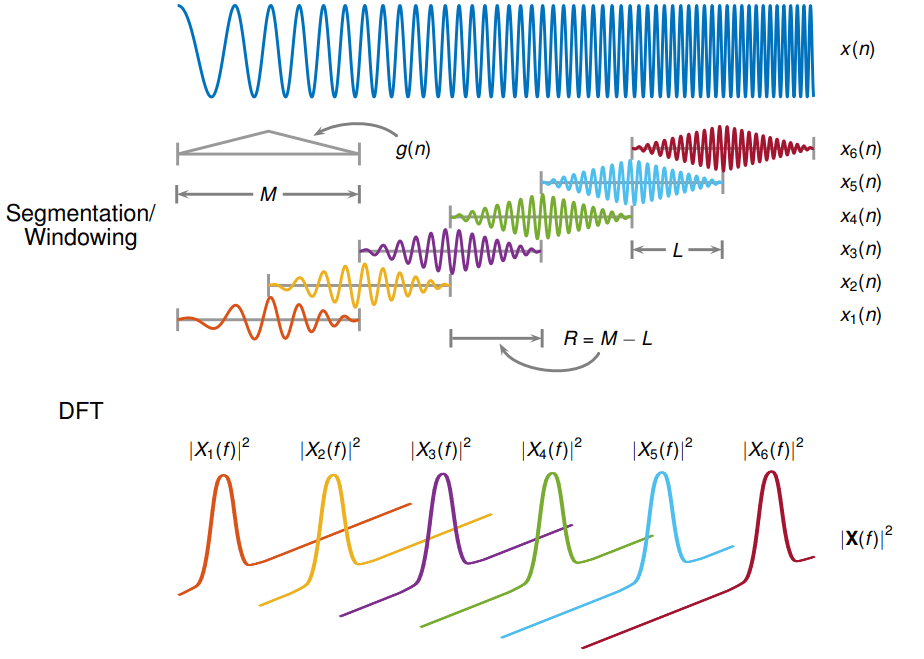

## Dataset

### Generate Signals

A chirp signal from 100 to 200 Hz in 2 secods

ts = 0:1/1e3:2;
f0 = 100;
f1 = 200;

% x = chirp(ts,f0,1,f1,'quadratic',[],'concave');
x = chirp(ts,f0,1,f1);

### STFT - one-sided

Compute and display the STFT of the quadratic chirp with a duration of 1 ms.

- Fs= 1000Hz.

- Divide Segments with 128 data points

- STFT Overlap of 50 datapoints

- DFT length as 128(default) with Hamming window 

% 1000 hz sampling frequency
fs=1e3;

[S,F,T] = stft(x, fs, 'Window', hamming(128,'periodic'), 'OverlapLength',50, 'FrequencyRange','onesided')

S =   -0.0019 + 0.0000i  -0.1245 + 0.0000i   0.1839 + 0.0000i  -0.1333 + 0.0000i  -0.0562 + 0.0000i   0.0858 + 0.0000i   0.1602 + 0.0000i  -0.0230 + 0.0000i   0.1284 + 0.0000i   0.1360 + 0.0000i  -0.0967 + 0.0000i   0.0498 + 0.0000i  -0.1035 + 0.0000i   0.1256 + 0.0000i   0.1217 + 0.0000i  -0.0817 + 0.0000i   0.0707 + 0.0000i  -0.0423 + 0.0000i   0.0747 + 0.0000i   0.0446 + 0.0000i   0.0570 + 0.0000i   0.0800 + 0.0000i   0.1006 + 0.0000i  -0.0974 + 0.0000i  -0.0902 + 0.0000i
  -0.0022 + 0.0148i  -0.1251 + 0.0077i   0.1844 + 0.0084i  -0.1338 + 0.0041i  -0.0565 + 0.0074i   0.0862 - 0.0051i   0.1606 + 0.0026i  -0.0229 - 0.0072i   0.1286 + 0.0061i   0.1362 + 0.0050i  -0.0967 - 0.0059i   0.0499 - 0.0032i  -0.1036 - 0.0051i   0.1257 + 0.0031i   0.1218 + 0.0032i  -0.0817 - 0.0044i   0.0708 - 0.0008i  -0.0423 - 0.0037i   0.0747 + 0.0038i   0.0446 + 0.0034i   0.0571 - 0.0006i   0.0800 + 0.0033i   0.1007 + 0.0022i  -0.0974 - 0.0020i  -0.0903 - 0.0029i
  -0.0032 + 0.0299i  -0.1272 + 0.0155i   0.1

F =          0
    7.8125
   15.6250
   23.4375
   31.2500
   39.0625
   46.8750
   54.6875
   62.5000
   70.3125


T =     0.0640
    0.1420
    0.2200
    0.2980
    0.3760
    0.4540
    0.5320
    0.6100
    0.6880
    0.7660


Visualize the STFT of each channel as a waterfall plot. 

Control the behavior of the axes using the helper function `helperGraphicsOpt`.

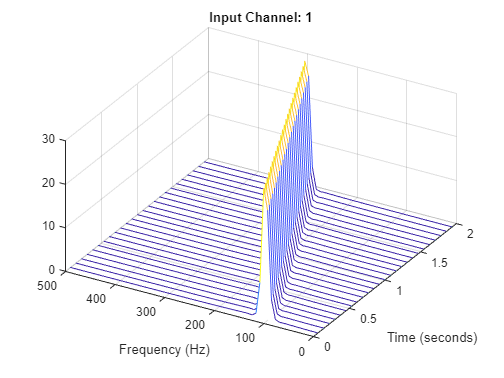

figure
waterfall(F,T,abs(S)')
helperGraphicsOpt(1)

### STFT - Spectogram PSD

You can also use spectogram for STFT. This plots PSD of each segment.

- Fs= 1 kHz, 

- Divide segments by length of 128 samples

- Overlap of 50 samples. 

- Use 128 DFT points and the default Hamming window.    

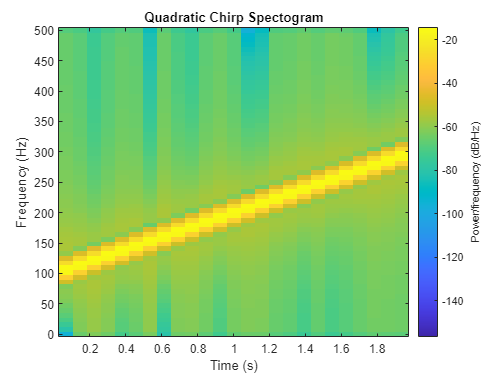

spectrogram(x, 128, 50, 128, fs, 'yaxis')
title('Quadratic Chirp Spectogram')

`%helperGraphicsOpt(1)`

function helperGraphicsOpt(ChannelId)
ax = gca;
ax.XDir = 'reverse';
ax.ZLim = [0 30];
ax.Title.String = ['Input Channel: ' num2str(ChannelId)];
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = 'Time (seconds)';
ax.View = [30 45];
end